# Train Hardware Soft Robot

clear vars; close all; clc;
warning('off','all')

% Number of observables
numObs = 15;
% Define modes
SSMDim = 6; hSSMDim = SSMDim/2;
rdof = hSSMDim; odof = rdof;
load obsDecayDataC
% load obsDecayDataC_withTop

## Visualize Training Data

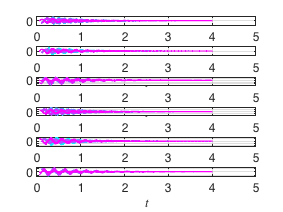

trajs = [13, 14, 15];
trajVel = [28, 29, 30];
allTraj = [trajs, trajVel];

numCoord = length(allTraj);
customFigure('subPlot',[numCoord 1]);

% Plot tip [position, velocity]
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(allTraj(iObs),:),'Linewidth',1)
    end
end

Consider only the tip positions, neglect other sensor data in this script.

tipData = oData;
for iTraj = 1:size(oData, 1)
    tipData{iTraj,2} = oData{iTraj,2}([trajs, trajVel],:);
end

Perform delay-embedding. As observables for the model, we consider the current tip position data as well as past measurements (no future ones) of the tip position data. For this case (we only consider the tip), we have a minimum of `4` delays, which is augmented by the `overEmbed` variable, so that the number of total delays is `4+overEmbed`. We also do some cutting, but it is not necessary in this current case.

overEmbed = 2;
[yData, opts_embd] = coordinatesEmbeddingControl(tipData, SSMDim, 'OverEmbedding', overEmbed);

The 30 embedding coordinates consist of the 6 measured states and their 4 time-delayed measurements.


embedDim = size(yData{1,2},1);
outdofs = [embedDim-5 embedDim-4 embedDim-3 ...
    embedDim-2 embedDim-1 embedDim];
sliceInt = [0.01, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);

PCA is still useful in the delay-embeeded space, as the number of modes explaining most of the data should be the dimension of the SSM. Indeed, we get it as more than 90% of variance is explained by the first six PCA modes.

disp('PCA')

PCA


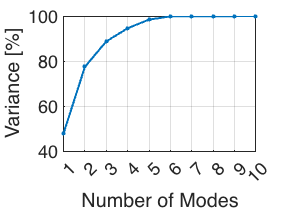

Xsnapshots = cat(2,yDataTrunc{:,2});
% Perform SVD on displacement field
[V,S,~] = svd(Xsnapshots, 0);
% Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
maxModesPlot = 10;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 maxModesPlot])
set(gca,'XTick',[1:1:maxModesPlot])


Vde = V(:,1:SSMDim);
% Set reduced-coordinates as PCA projection to the first six modes
etaDataTrunc = yDataTrunc;
for iTraj = 1:size(oData, 1)
    etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
end

% Set test and train trajectories
indTest = [5 15 21 22 28];
indTrain = setdiff(1:size(oData, 1),indTest);

## Geometry

Manifold fitting with prescribed graph. Higher orders tend to overfit.

SSMOrder = 3;
if SSMOrder == 1
    % Need to recompute as the columns of Vde might change in order
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);
    Vde = IMInfo.parametrization.tangentSpaceAtOrigin;
    etaDataTrunc = yDataTrunc;
    for iTraj = 1:size(oData, 1)
        etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
    end
else
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc(indTrain,:));
    IMInfo.chart.map = @(x) transpose(Vde)*x;
end

Evaluate learning of geometry.

%% Trajectory lifting requires reduced coordinates (ensures y is on manifold, 
% hence yRec =/= yDataTrunc)
disp('Results of geometry fit:')

Results of geometry fit:


yRec = liftTrajectories(IMInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 0.6670

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 0.5972

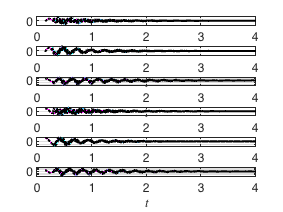


% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Reduced dynamics

Cubic order dynamics halves the trajectory error of linear dynamics. The `Map` case seems more accurate than the `Flow` one.

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -1.8072 +24.0066i
  -1.5892 +26.2999i
  -1.1684 +26.8067i


Rauton = RDInfo.reducedDynamics.map

Rauton = function_handle with value:
    @(x)W_r*phi(x)

Evaluate learning of reduced dynamics.

disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = Inf

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = Inf

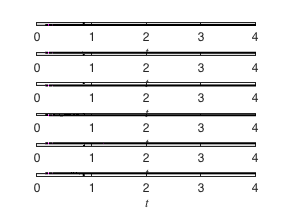

yRec = liftTrajectories(IMInfo, etaRec);

% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

% Define custom chart only based on tip data and velocity
yDataTruncNew = yDataTrunc;
etaDataTrunc2 = etaDataTrunc;
for iTraj = 1:size(yData,1)
    % yDataTruncNew{iTraj,1} = time;
    yDataTruncNew{iTraj,2} = yDataTruncNew{iTraj,2}(outdofs,:);
    etaDataTrunc2{iTraj,1} = etaDataTrunc{iTraj,1}(1:end);
    etaDataTrunc2{iTraj,2} = etaDataTrunc{iTraj,2}(:,1:end);
    %[etaDataTrunc2{iTraj,1}(1)-yDataTruncNew{iTraj,1}(1) etaDataTrunc2{iTraj,1}(end)-yDataTruncNew{iTraj,1}(end)]
end
%%
IMInfo_paramonly = IMGeometry(yDataTruncNew(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc2(indTrain,:),'style','custom');
tanSpace0_not_orth = IMInfo_paramonly.parametrization.tangentSpaceAtOrigin;
tanSpace0 = orthogonalizeGramSchmidt(tanSpace0_not_orth);
% Change coordinates
etaDataTruncNew = etaDataTrunc2;
for iTraj = 1:size(etaDataTrunc,1)
    etaDataTruncNew{iTraj,2} = transpose(tanSpace0)*tanSpace0_not_orth*etaDataTrunc2{iTraj,2};
end
% Fit new parametrization
IMInfo_paramonly = IMGeometry(yDataTruncNew(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTruncNew(indTrain,:),'Ve',tanSpace0,'style','custom');
disp('Results of new parametrization fit:')

Results of new parametrization fit:


yRec = liftTrajectories(IMInfo_paramonly, etaDataTruncNew);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTruncNew);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 0.6359

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 0.5765


IMInfo_chartonly = IMGeometry(etaDataTruncNew(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',yDataTruncNew(indTrain,:),'Ve',transpose(tanSpace0),'style','custom');
disp('Results of new chart fit:')

Results of new chart fit:


etaRec = liftTrajectories(IMInfo_chartonly, yDataTruncNew);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTruncNew);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 0.6367

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 0.5981

IMInfo = struct('chart', IMInfo_chartonly.parametrization, 'parametrization', IMInfo_paramonly.parametrization);

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTruncNew(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -1.8072 +24.0066i
  -1.5892 +26.2999i
  -1.1684 +26.8067i


Rauton = RDInfo.reducedDynamics.map;
disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaRec);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTruncNew);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = Inf

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = Inf

yRec = liftTrajectories(IMInfo, etaRec);

disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaRec);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTruncNew);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = Inf

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = Inf

yRec = liftTrajectories(IMInfo, etaRec);
outdofsNew = [1 2 3 4 5 6];

% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); indPlot = indTest; %indTrain(isinf(normedTrajDist(indTrain)) == 0);

labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt); colororder(cool(length(indPlot)));
    xlabel('$t$','Interpreter','latex');
end
for iTraj = 1:length(indPlot)
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(yDataTruncNew{indPlot(iTraj),1},yDataTruncNew{indPlot(iTraj),2}(outdofsNew(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indPlot)
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(yRec{indPlot(iTraj),1},yRec{indPlot(iTraj),2}(outdofsNew(iObs),:),'k:','Linewidth',2)
    end
end

**Verify Projection and Manifold maps on Controlled Trajectory**

% load obsDataInput
load obsDataInput_withCircle
% load obsDataInput_circleFocus

Yu = oData;
outdofs = [13 14 15 28 29 30];
for iTraj = 1:size(Yu, 1)
    Yu{iTraj, 2} = Yu{iTraj, 2}(outdofs, :);
end
% v then w mapping
xData = projectTrajectories(IMInfo, Yu); % Project down
yDataRemapped = liftTrajectories(IMInfo, xData); % Project up

% Plot data
outdofsNew = [1 2 3 4 5 6]

outdofsNew =      1     2     3     4     5     6


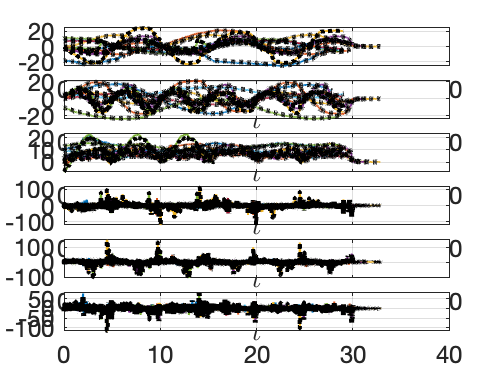

customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
end

% (TODO) Neglecting: 1, 4, 7 (noisy)
% 2, 3 have weird offsets
% Vertical circle = 14

% For circle trajectory
% ctrlTrajs = [1 4 5 6 7 8 9 10 11 12 13 14];

% Somehow this choice leads to best figure 8 traj
ctrlTrajs = [5 6 8 9 10 11 12 13];

for iTraj = 1:size(ctrlTrajs,2)
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(Yu{ctrlTrajs(iTraj),1},Yu{ctrlTrajs(iTraj),2}(outdofsNew(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:size(ctrlTrajs,2)
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(yDataRemapped{ctrlTrajs(iTraj),1},yDataRemapped{ctrlTrajs(iTraj),2}(outdofsNew(iObs),:),'k:','Linewidth',2)
    end
end

## Learn control matrix

From theory, we expect the following corrections in the reduced order model:


$$\dot{\mathit{\mathbf{x}}} =\mathit{\mathbf{r}}\left(\mathit{\mathbf{x}}\right)+{\mathit{\mathbf{B}}}_{\mathit{\mathbf{r}}} \mathit{\mathbf{u}}\left(t\right)$$



$$\mathit{\mathbf{y}}=\mathit{\mathbf{v}}\left(\mathit{\mathbf{x}}\right)+{\mathit{\mathbf{B}}}_{\mathit{\mathbf{v}}} \int_0^t \mathit{\mathbf{u}}\left(s\right)\textrm{ds}$$


under the assumptions that the control action is small and that the dynamics of other structural modes can be neglected.

% Setup trajectories for fit
yuxData = cell(size(ctrlTrajs, 2),4);
for iTraj = 1:size(ctrlTrajs, 2)
   yuxData{iTraj,1} = Yu{ctrlTrajs(iTraj),1};
   yuxData{iTraj,2} = Yu{ctrlTrajs(iTraj),2};
   yuxData{iTraj,3} = Yu{ctrlTrajs(iTraj),4};
   yuxData{iTraj,4} = IMInfo.chart.map(Yu{ctrlTrajs(iTraj),2});
end
% Fit control matrices
[Br,Bv,regErrors] = fitControlMatrices(yuxData,RDInfo,IMInfo,0,0)

Br = 	1.0e+04 *

    0.4371    1.0104   -0.2663   -1.3654
    1.3365   -0.3432   -0.6989   -0.1151
   -0.6988   -0.5068   -0.6027   -0.6233
    0.0202    0.0375    0.0309    0.0198
    0.0219    0.0006    0.0024    0.0080
    0.0129    0.0084    0.0142    0.0187


Bv =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


regErrors =    11.7342       NaN


% Update models
Rauton = RDInfo.reducedDynamics.map;
R = @(t,x,u) Rauton(x) + Br*u;
Vauton = IMInfo.parametrization.map;
V = @(x,u_int) Vauton(x) + Bv*u_int;

**Validate Control model**

iTraj = 5; %TODO: Edit this for validating against specific trajectory
ti = yuxData{iTraj,1};
yi = yuxData{iTraj,2};
ui = yuxData{iTraj,3};
xi = yuxData{iTraj,4};
uiInt = integrateTimeSeries(ui,ti(2)-ti(1));

Check Local controllability and observability

Ac = RDInfo.reducedDynamics.coefficients(1:SSMDim, 1:SSMDim);
Bc = Br;
Cc = IMInfo.parametrization.H(1:SSMDim, 1:SSMDim);

isControllable = (length(Ac) == rank(ctrb(Ac, Bc)))

isControllable = logical
   1

isObservable = (length(Cc) == rank(obsv(Ac, Cc)))

isObservable = logical
   1

Check geometry

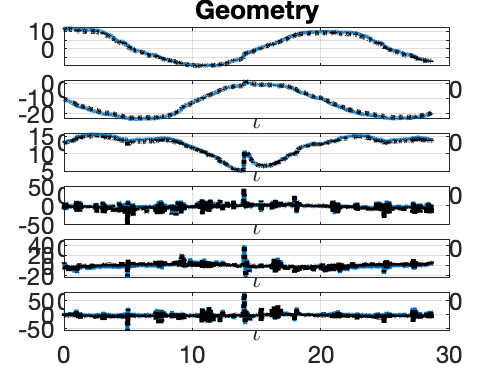

yiRec = V(xi,uiInt);
zi = yi(outdofsNew,:); ziRec = yiRec(outdofsNew,:); 

% Plot time series
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title ('Geometry')
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
end
for iObs = 1:length(outdofsNew)
    subplot(numCoord,1,iObs);
    plot(ti, zi(iObs, :),'Linewidth',2);
end
for iObs = 1:length(outdofsNew)
    subplot(numCoord,1,iObs);
    plot(ti, ziRec(iObs, :),'k:','Linewidth',2);
end

Check dynamics

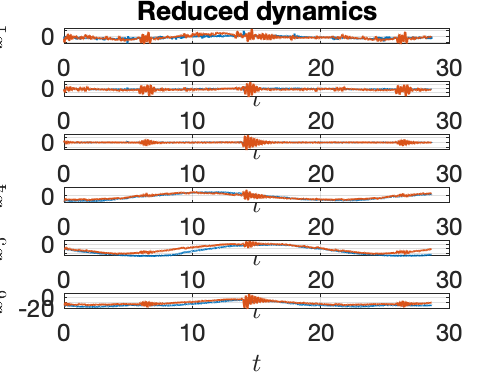

uFun = @(t) transpose(interp1(ti, transpose(ui), t));
[tiPred,xiPred] = ode45(@(t,x) R(t,x,uFun(t)),ti,xi(:,1)); 
tiPred = transpose(tiPred); xiPred = transpose(xiPred); 

% Plot time series
customFigure('subPlot',[6 1]);
labelsRD = {'$x_1$', '$x_2$', '$x_3$', '$x_4$', '$x_5$', '$x_6$'};
subplot(6,1,1); title ('Reduced dynamics')
for iPlt = 1:6
    subplot(6,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labelsRD(iPlt),'Interpreter','latex');
end
for iObs = 1:6
    subplot(6,1,iObs);
    plot(ti, xi(iObs, :),'Linewidth',1);
end
for iObs = 1:6
    subplot(6,1,iObs);
    plot(tiPred, xiPred(iObs, :),'Linewidth',1);
end

Check overall reduced-order model

outdofsNew = [1 2 3 4 5 6]

outdofsNew =      1     2     3     4     5     6


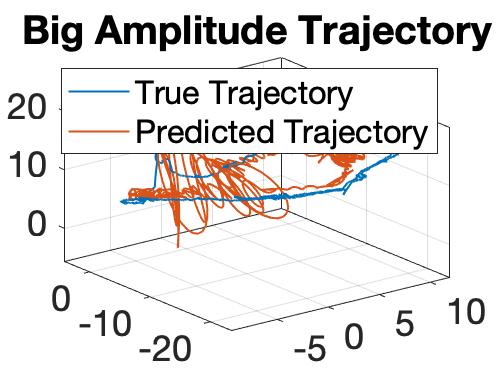

nStepsPred = length(tiPred);
if nStepsPred<length(ti)
   tiPred(nStepsPred+1:length(ti)) = NaN; xiPred(:,nStepsPred+1:length(ti)) = NaN; 
end
yiPred = V(xiPred,uiInt);
zi = yi(outdofsNew,:); ziPred = yiPred(outdofsNew,:);

% Visualize the trajectory in 3d
customFigure;
plot3(zi(1, :), zi(2, :), zi(3, :),'Linewidth',1);
plot3(ziPred(1, :), ziPred(2, :), ziPred(3, :),'Linewidth',1);
legend('True Trajectory', 'Predicted Trajectory');
title('Big Amplitude Trajectory');
view(3);


RMSE = sum(sqrt(mean((ziPred(1:3, :) - zi(1:3,:)).^2))) / size(ziPred, 2)

RMSE = 3.6345


outdofsNew = [1 2 3 4 5 6]

outdofsNew =      1     2     3     4     5     6


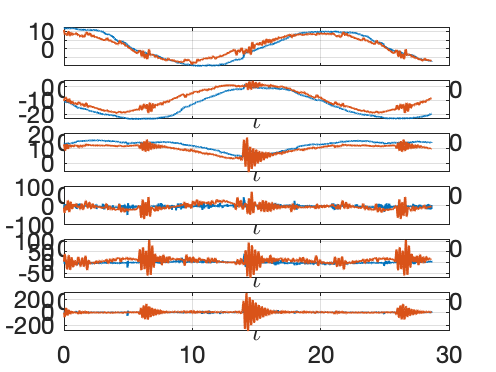

% Plot time series
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
end
for iObs = 1:length(outdofsNew)
    subplot(numCoord,1,iObs);
    plot(ti, zi(iObs, :),'Linewidth',1);
end
for iObs = 1:length(outdofsNew)
    subplot(numCoord,1,iObs);
    plot(tiPred, ziPred(iObs, :),'Linewidth',1);
end

**Validate short time Control model**

Nhoriz = 100;
etaData = Yu;
for iTraj=1:size(ctrlTrajs, 1)
    etaData{iTraj,2} = IMInfo.chart.map(Yu{ctrlTrajs(iTraj),2});
end
nEval = length(Yu{ctrlTrajs(iTraj),1})-Nhoriz;
yDataPredHoriz = cell(1,5);
iRow = 1;
for iTime = 1:nEval
    uHoriz = Yu{ctrlTrajs(iTraj),4}(:,iTime:iTime+Nhoriz);
    tHoriz = Yu{ctrlTrajs(iTraj),3}(iTime:iTime+Nhoriz);
    uFun = @(t) transpose(interp1(tHoriz, transpose(uHoriz), t));
    [iTimeRec, ietaRec] = ode15s(@(t,x) R(t,x,uFun(t)),tHoriz,etaData{1,2}(:,iTime));
    % Lift
    iyRec = liftTrajectories(IMInfo, {iTimeRec, transpose(ietaRec)});
    
    yDataPredHoriz{iRow,1} = etaData{ctrlTrajs(iTraj),1}(iTime:iTime+Nhoriz);
    yDataPredHoriz{iRow,2} = ietaRec(:,:);
    yDataPredHoriz{iRow,3} = etaData{ctrlTrajs(iTraj),1}(iTime+Nhoriz);
    yDataPredHoriz{iRow,4} = iyRec{1,2}(outdofsNew,:);
    yDataPredHoriz{iRow,5} = iTime;
    iRow = iRow + 1;
end

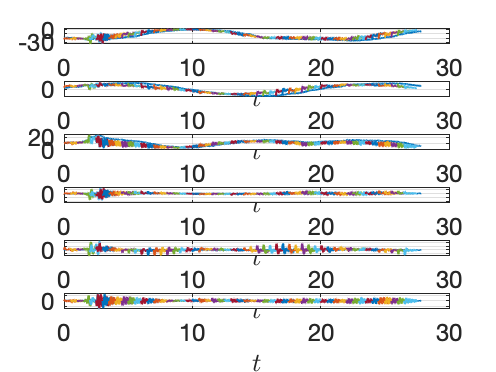

% Plot time series
idxPlotCL = 50;
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
end
for iObs = 1:length(outdofsNew)
    subplot(numCoord,1,iObs);
    plot(Yu{ctrlTrajs(iTraj),1}, Yu{ctrlTrajs(iTraj),2}(iObs, :),'Linewidth',1);
end
for iObs = 1:length(outdofsNew)
    subplot(numCoord,1,iObs);
    for iTraj=1:idxPlotCL:size(yDataPredHoriz,1)
        plot(yDataPredHoriz{iTraj,1}, yDataPredHoriz{iTraj,4}(iObs,:),'Linewidth',1);
    end
end

## Export mapping coefficients and input matrix

% Continuous-time model
Ts = 0.01;
% TODO: Save either known input matrix or learned input matrix
% B_r = [zeros(rdof,size(Hred,2)); Hred];
B_r = Br;
w_coeff = IMInfo.parametrization.H; % reduced to observed
v_coeff = IMInfo.chart.H; % observed to reduced
r_coeff = RDInfo.reducedDynamics.coefficients;
Vde = [];
delays = 0;

py_data = struct();
ssm_model = struct();

ssm_model.w_coeff = w_coeff;
ssm_model.v_coeff = v_coeff;
ssm_model.r_coeff = r_coeff;
ssm_model.B = B_r;
ssm_model.V = Vde;

ssm_model.Ts = Ts;
py_data.model = ssm_model;

params = struct();
params.SSM_order = SSMOrder;
params.ROM_order = ROMOrder;
params.state_dim = 2*rdof;
params.input_dim = size(B_r, 2);
params.output_dim = 2*odof;
params.delays = delays;
params.obs_dim = 2*odof; % For testing new functionality
py_data.params = params;

save('SSM_model_embed2.mat', 'py_data', '-v7')